# Discrete SIR Model

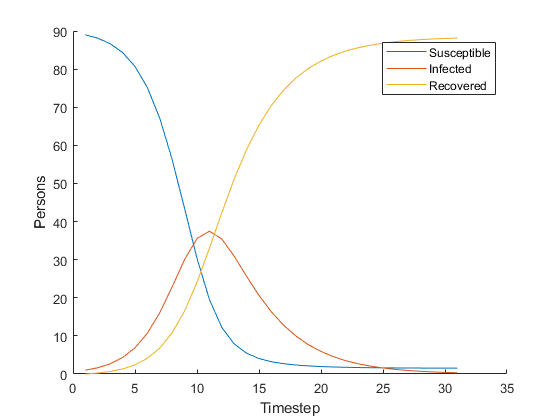

% Define parameters
tab_state = fcn_make_table( ...
    "s", 89, ...
    "i", 1, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", 0.01, "gamma", 0.25);

% Run simulation
tab_record = fcn_simulate(tab_state, tab_system, 30);

% Plot
figure(1); clf; hold on;
plot(tab_record.s); label1 = "Susceptible";
plot(tab_record.i); label2 = "Infected";
plot(tab_record.r); label3 = "Recovered";

xlabel("Timestep")
ylabel("Persons")
legend({label1, label2, label3})

describe(tab_record)

ans = 6×4 table
      s          i         r         stat  
    ______    _______    ______    ________

        89     37.474    88.151    "Max"   
    53.052     19.536    86.125    "Q3"    
    25.177     11.385    53.438    "Mean"  
    3.2209     5.9086    70.481    "Median"
    1.6621     1.5925    12.273    "Q1"    
    1.5317    0.31776         0    "Min"   
